% Crear la variable de trabajo a partir de los datos en bruto
A = rawdata(:, ["Type", "PCDate", "PCTime", "GPSDate", "gpsTime", "stdVal", "CO2Umm", "latitude", "longitude", "H2OFlow", "licorFlow", "equTemp", "licorTemp", "IntakeTemp", "TSGTemp", "Temp", "licorPress", "atmPress", "equPress", "Oxygen", "TSGSalt"]);

Error using  () 
Unrecognized table variable name 'GPSDate'.


% Añadir la variable de fecha y quitar las variables de GPSDate y gpsTime
A.GPSDate.Format = "dd/MM/uuuu HH:mm:ss";
A.gpsTime.Format = "dd/MM/uuuu HH:mm:ss";

A.PCDate.Format = "dd/MM/uuuu HH:mm:ss";
A.PCTime.Format = "dd/MM/uuuu HH:mm:ss";

for k=1:numel(A.GPSDate)
    if isnat(A.GPSDate(k))
        A.Date(k) = A.PCDate(k) + timeofday(A.PCTime(k));
    else
        A.Date(k) = A.GPSDate(k) + timeofday(A.gpsTime(k));
    end 
end

A.JulianDate = exceltime(A.Date);
A.GPSDate = [];
A.gpsTime = [];

A.PCDate = [];
A.PCTime = [];

% Hallar filas que dieron NaN y eliminarlas
% noTime = find(isnan(A.JulianDate(A.Type ~= "STD2")));
% A(noTime, :) = [];
nonDate = find(isnan(A.JulianDate));
A(nonDate, :) = [];

% Añadir las variables de presión en atm y quitar las variables en bares
A.licorPress2 = A.licorPress * 0.000986923;
A.atmPress2 = A.atmPress * 0.000986923;
A.equPress2 = A.equPress * 0.000986923;

A.licorPress = [];
A.atmPress = [];
A.equPress = [];

% Hacer NaN los valores de TEMP y SAL que son 0
disp(numel(A.TSGTemp(A.TSGTemp == 0)) + " TSG temperature values in " + numel(A.TSGTemp) + " values are 0.");
disp(numel(A.TSGSalt(A.TSGSalt == 0)) + " salinity temperature values in " + numel(A.TSGSalt) + " values are 0.");

A.TSGTemp = standardizeMissing(A.TSGTemp, 0);
A.TSGSalt = standardizeMissing(A.TSGSalt, 0);

disp(numel(find(isnan(A.TSGTemp))) + " TSG temperature values are now NaN.");
disp(numel(find(isnan(A.TSGSalt))) + " salinity values are now NaN.");

% Encontrar valores nulos de temperatura
nullInt = find(isnan(A.IntakeTemp));
nullTSG = find(isnan(A.TSGTemp));
nullEqu = find(isnan(A.equTemp));

disp(numel(nullInt) + " Intake temperature values are NaN.");
disp(numel(nullTSG) + " TSG temperature values are NaN.");
disp(numel(nullEqu) + " Equ temperature values are NaN.");

% Encontrar valores erróneos de temperatura
badInt = find(A.IntakeTemp > 30 | A.IntakeTemp < 14);
badTSG = find(A.TSGTemp > 35 | A.TSGTemp < 14);
badEqu = find(A.equTemp > 35 | A.equTemp < 14);

disp("There are " + numel(badInt) + " wrong Intake Temperature values in " + numel(A.IntakeTemp) + " values.");
disp("There are " + numel(badTSG) + " wrong TSG Temperature values in " + numel(A.TSGTemp) + " values.");
disp("There are " + numel(badEqu) + " wrong Equ Temperature values in " + numel(A.equTemp) + " values.");

% Convertir en NaN los valores erróneos de temperatura
A.IntakeTemp = standardizeMissing(A.IntakeTemp, A.IntakeTemp(badInt));
A.TSGTemp = standardizeMissing(A.TSGTemp, A.TSGTemp(badTSG));
A.equTemp = standardizeMissing(A.equTemp, A.equTemp(badEqu));

disp(numel(find(isnan(A.IntakeTemp))) + " Intake temperature values are now NaN.");
disp(numel(find(isnan(A.TSGTemp))) + " TSG temperature values are now NaN.");
disp(numel(find(isnan(A.equTemp))) + " Equ temperature values are now NaN.");

% Añadir las variables de diferencia de temperatura 
A.DiffEquInt = A.equTemp - A.IntakeTemp;
A.DiffTSGint = A.TSGTemp - A.IntakeTemp;
A.DiffEquTSG = A.equTemp - A.TSGTemp;

% Hallar diferencias de temperatura mayores de 2 grados y menores de cero,
% así como valores NaN
badDiffEquInt= find(abs(A.DiffEquInt) > 2 | A.DiffEquInt < 0);
badDiffEquInt2 = find(abs(A.DiffEquInt) > 1.5 | A.DiffEquInt < 0);
nullDiffEquInt = find(isnan(A.DiffEquInt));

disp(numel(nullDiffEquInt) + " difference values are NaN.");
disp("There are " + numel(badDiffEquInt) + " bad difference values (some of them are > 2) in " + numel(A.DiffEquInt) + " values.");
disp("There are " + numel(badDiffEquInt2) + " bad difference values (some of them are > 1.5) in " + numel(A.DiffEquInt) + " values.");

% Convertir en NaN estos valores de diferencia de temperatura
A.DiffEquInt = standardizeMissing(A.DiffEquInt, A.DiffEquInt([badDiffEquInt; badDiffEquInt2]));
allNullDiffEquInt = find(isnan(A.DiffEquInt));
CO2nullDiffEquInt = find(A.Type == "EQU" & isnan(A.DiffEquInt));
disp(numel(find(allNullDiffEquInt)) + " Equ-Int difference values are now NaN.");
disp(numel(CO2nullDiffEquInt) + " Equ-Int difference values for Equ CO2 are NaN.");

% Encontrar valores erróneos de salinidad y convertirlos en NaN. Hallar
% también valores NaN inicialmente
badSAL = find(A.TSGSalt < 34);
nullSAL = find(isnan(A.TSGSalt));
disp(numel(nullSAL) + " Salinity values are NaN.");
disp("There are " + numel(badSAL) + " wrong salinity values in " + numel(A.TSGSalt) + " values.");
A.TSGSalt = standardizeMissing(A.TSGSalt, A.TSGSalt(badSAL));
disp(numel(find(isnan(A.TSGSalt))) + " salinity values are now NaN.");

% Encontrar valores erróneos de presión atmosférica y convertirlos en NaN.
% Hallar también valores NaN iniciales
badPress = find(A.atmPress2 < 0.9);
nullPress = find(isnan(A.atmPress2));
disp(numel(nullPress) + " atm pressure values are NaN.");
disp("There are " + numel(badPress) + " wrong pressure values in " + numel(A.atmPress2) + " values.");
A.atmPress2 = standardizeMissing(A.atmPress2, A.atmPress2(badPress));
disp(numel(find(isnan(A.atmPress2))) + " pressure values are now NaN.");

% Encontrar valores erróneos de flujo de agua en el equilibrador y convertirlos en NaN.
% Hallar también valores NaN iniciales
badH2O = find(A.H2OFlow < 2.5);
nullH2O = find(isnan(A.H2OFlow));
disp(numel(nullH2O) + " H2O flow values are NaN.");
disp("There are " + numel(badH2O) + " wrong H2O flow values in " + numel(A.H2OFlow) + " values.");
%A.H2OFlow = standardizeMissing(A.H2OFlow, A.H2OFlow(badH2O));
allNullH2O = find(isnan(A.H2OFlow));
disp(numel(allNullH2O) + " H2O flow values are now NaN.");
CO2nullH2O = find(A.Type == "EQU" & isnan(A.H2OFlow));
disp(numel(CO2nullH2O) + " H2O flow values for Equ CO2 are NaN.");

% Encontrar valores erróneos de CO2 y convertirlos en NaN. Eliminar también
% valores para los que la temperatura y el flujo de agua son erróneos
badCO2 = find(A.Type == "EQU" & (A.CO2Umm > 500 | A.CO2Umm < 360));
disp("There are " + numel(badCO2) + " bad CO2 values in " + numel(A.CO2Umm) + " values.");
disp("There are " + numel(find(isnan(A.CO2Umm))) + " NaN CO2 values in " + numel(A.CO2Umm) + " values.");

%A.CO2Umm(sort([CO2nullDiffEquInt;CO2nullH2O;badCO2])) = NaN; 
disp(numel(find(isnan(A.CO2Umm))) + " CO2 values in " + numel(A.CO2Umm) + " are now NaN.");

% Recolocar las columnas en la tabla
A = movevars(A, ["DiffEquInt" "DiffTSGint", "DiffEquTSG"], "After", "Temp");
A = movevars(A, ["Date", "JulianDate"], "After", "Type");

% Ordenar las filas por fecha
A = sortrows(A, "Date");

msgbox("Data table created");

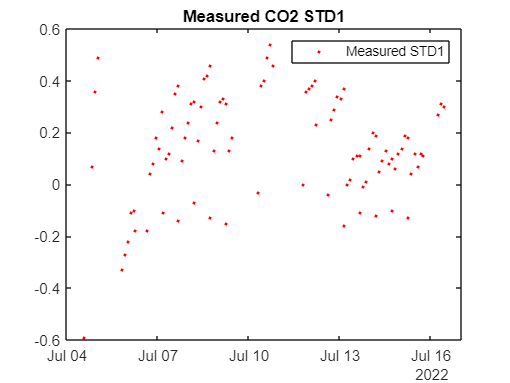

% Representar los valores medidos de los gases con su valor estándar

plot(A.Date(A.Type == "STD1"), A.CO2Umm(A.Type == "STD1"), ".r") % Gas 2
title("Measured CO2 STD1")
legend("Measured STD1", "Location", "northeast")

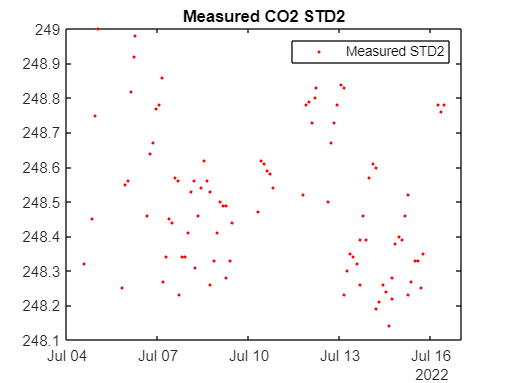


plot(A.Date(A.Type == "STD2"), A.CO2Umm(A.Type == "STD2"), ".r") % Gas 2
title("Measured CO2 STD2")
legend("Measured STD2", "Location", "northeast")

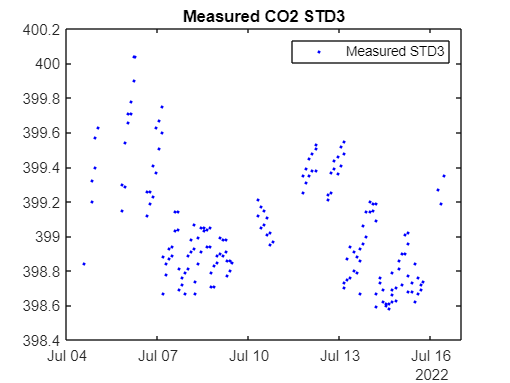


plot(A.Date(A.Type == "STD3"), A.CO2Umm(A.Type == "STD3"), ".b") % Gas 3
title("Measured CO2 STD3")
legend("Measured STD3", "Location", "northeast")

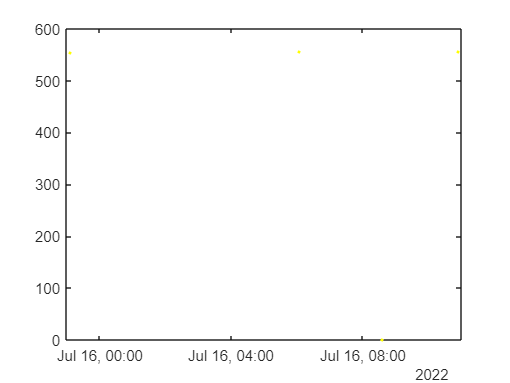


plot(A.Date(A.Type == "STD4"), A.CO2Umm(A.Type == "STD4"), ".y") % Gas 4

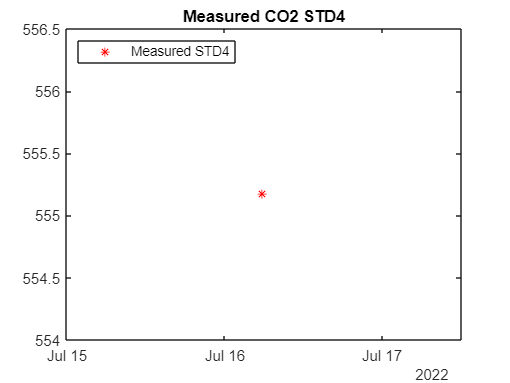

plot(A.Date(A.Type == "STD4s"), A.CO2Umm(A.Type == "STD4s"), "*r")
hold off
title("Measured CO2 STD4")
legend("Measured STD4", "STD4s", "Location", "northwest")

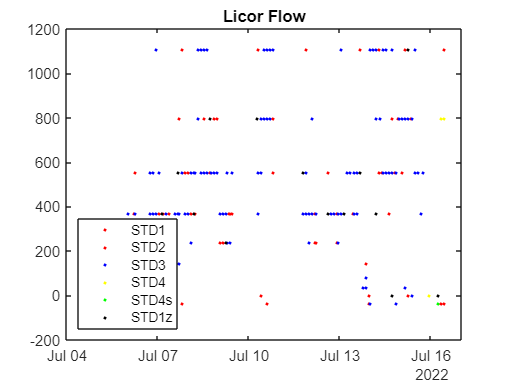



% Representar licor flow de los gases y de las mediciones atmosféricas y
% equilibrador
plot(A.Date(A.Type == "STD1"), A.licorFlow(A.Type == "STD1"), ".r") 
hold on
plot(A.Date(A.Type == "STD2"), A.licorFlow(A.Type == "STD2"), ".r") 
hold on
plot(A.Date(A.Type == "STD3"), A.licorFlow(A.Type == "STD3"), ".b")
hold on
plot(A.Date(A.Type == "STD4"), A.licorFlow(A.Type == "STD4"), ".y")
hold on
plot(A.Date(A.Type == "STD4s"), A.licorFlow(A.Type == "STD4s"), ".g")
hold on
plot(A.Date(A.Type == "STD1z"), A.licorFlow(A.Type == "STD1z"), ".k")
hold off
title("Licor Flow")
legend("STD1", "STD2", "STD3", "STD4", "STD4s", "STD1z", "Location", "southwest")

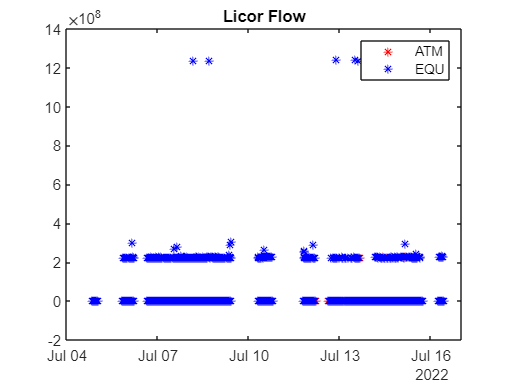


plot(A.Date(A.Type == "ATM"), A.licorFlow(A.Type == "ATM"), "*r")
hold on
plot(A.Date(A.Type == "EQU"), A.licorFlow(A.Type == "EQU"), "*b")
hold off
title("Licor Flow")
legend("ATM", "EQU")

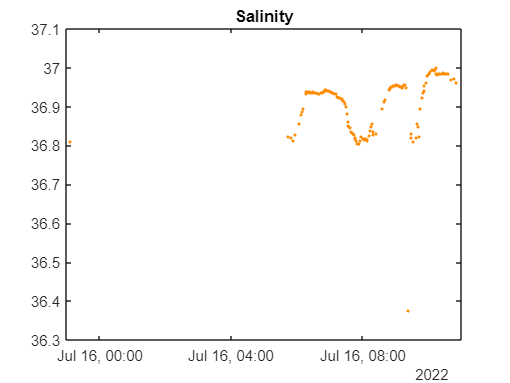

    

% Salinidad
plot(A.Date, A.TSGSalt, ".", "Color", "#FF8C00")
title("Salinity")

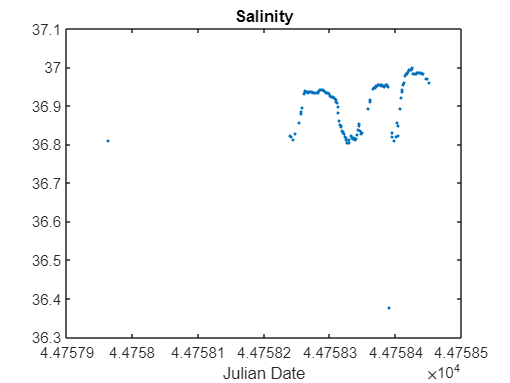

%ylim([35 39])

plot(A.JulianDate, A.TSGSalt, ".")
title("Salinity")
xlabel("Julian Date")

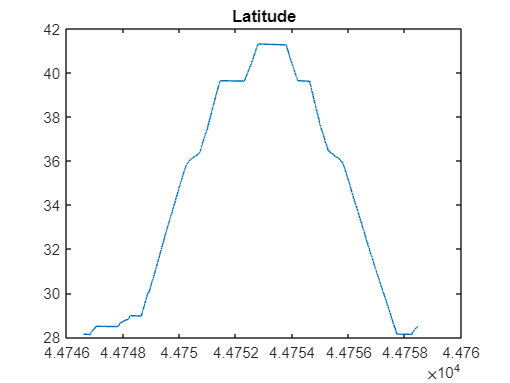

%ylim([35 39])


% Coordenadas
plot(A.JulianDate, A.latitude)
title("Latitude")

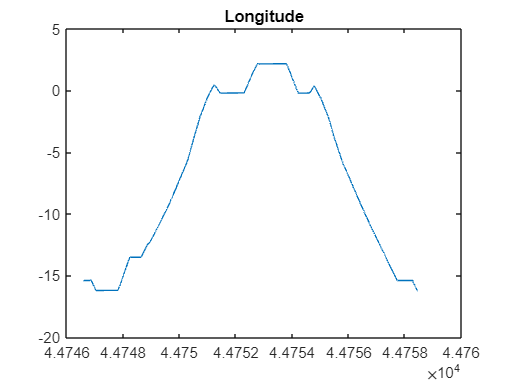


plot(A.JulianDate, A.longitude)
title("Longitude")

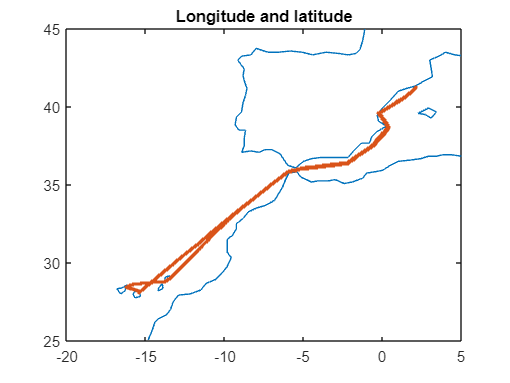


% Obtener las coordenadas máximas y mínimas medidas para comprobar si hay algún error
coord = table(min(A.longitude), min(A.latitude), max(A.longitude), max(A.latitude), 'VariableNames', {'minLon', 'minLat', 'maxLon', 'maxLat'});

load coastlines
plot(coastlon, coastlat)
hold on 
plot(A.longitude, A.latitude, ".")
hold off
title("Longitude and latitude")
xlim([-20 5])
ylim([25 45])

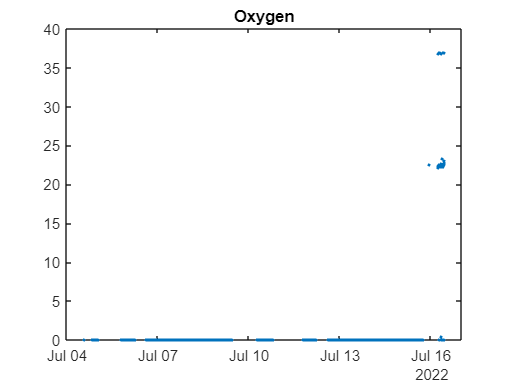



% Oxígeno
plot(A.Date, A.Oxygen, ".")
title("Oxygen")

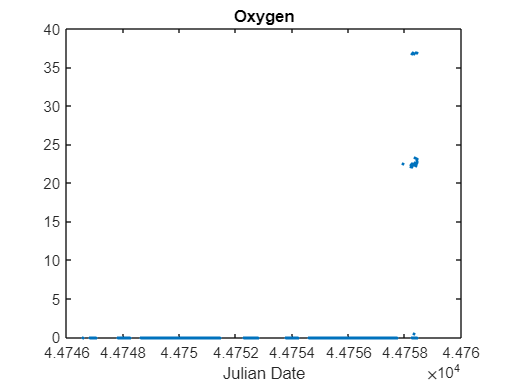

%ylim([200 350])

plot(A.JulianDate, A.Oxygen, ".")
title("Oxygen")
xlabel("Julian Date")

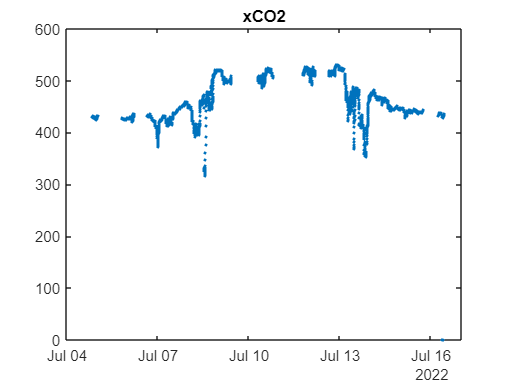

%ylim([200 350])


% xCO2 en el equilibrador
plot(A.Date(A.Type == "EQU"), A.CO2Umm(A.Type == "EQU"), ".")
title("xCO2")

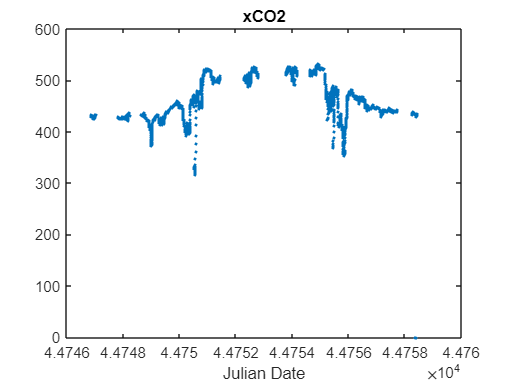

% ylim([350 550])

plot(A.JulianDate(A.Type == "EQU"), A.CO2Umm(A.Type == "EQU"), ".")
title("xCO2")
xlabel("Julian Date")

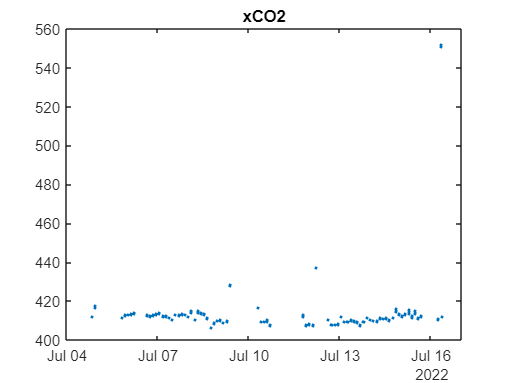

% ylim([350 550])


% xCO2 atmosférico
plot(A.Date(A.Type == "ATM"), A.CO2Umm(A.Type == "ATM"), ".")
title("xCO2")

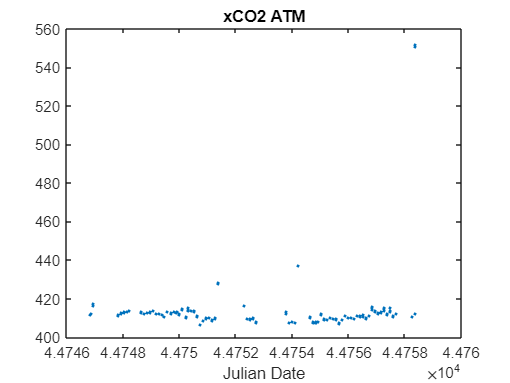

% ylim([350 550])

plot(A.JulianDate(A.Type == "ATM"), A.CO2Umm(A.Type == "ATM"), ".")
title("xCO2 ATM")
xlabel("Julian Date")

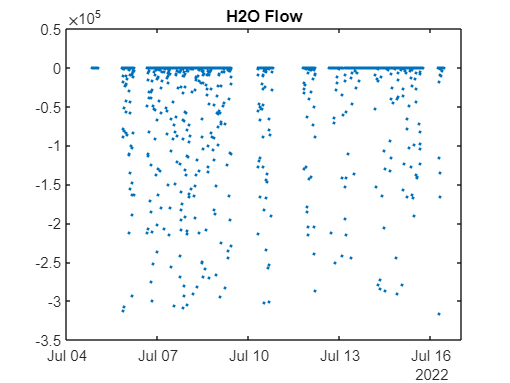

% ylim([350 550])


% Flujo de agua en el equilibrador
plot(A.Date(A.Type == "EQU"), A.H2OFlow(A.Type == "EQU"), ".")
% ylim([-0.5, 3.5])
title("H2O Flow")

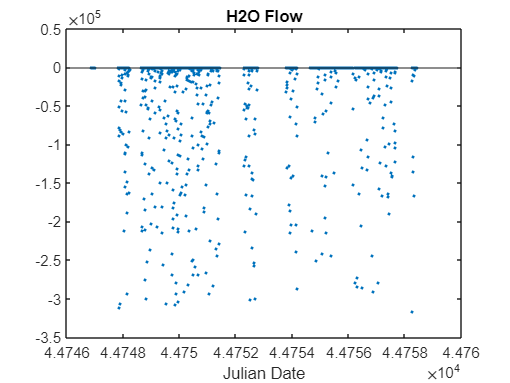

%ylim([0, 3.8])

plot(A.JulianDate(A.Type == "EQU"), A.H2OFlow(A.Type == "EQU"), ".")
hold on
yline(2.5)
hold off
% ylim([-0.5, 3.5])
title("H2O Flow")
xlabel("Julian Date")

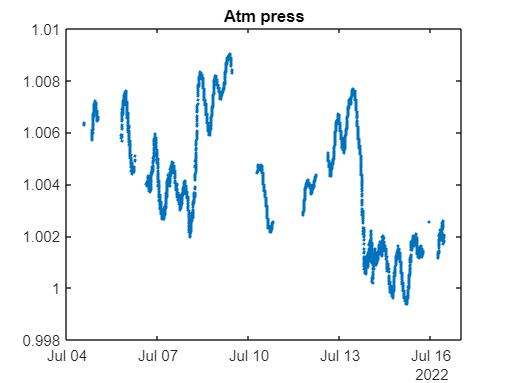



% Presiones

% Atm press
plot(A.Date, A.atmPress2, ".")
title("Atm press")

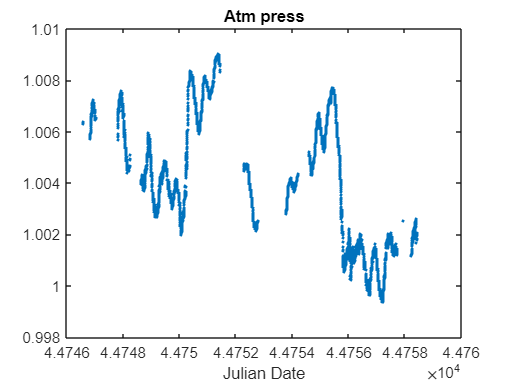

%ylim([0.97 1.03])

plot(A.JulianDate, A.atmPress2, ".")
title("Atm press")
xlabel("Julian Date")

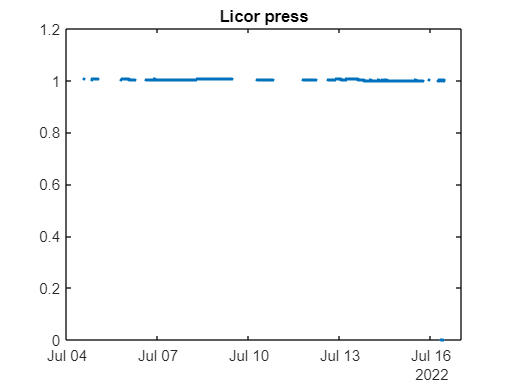

%ylim([0.97 1.03])

% Licor Press
plot(A.Date, A.licorPress2, ".")
title("Licor press")

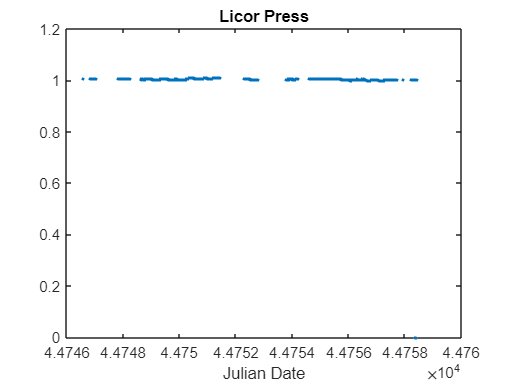


plot(A.JulianDate, A.licorPress2, ".")
title("Licor Press")
xlabel("Julian Date")

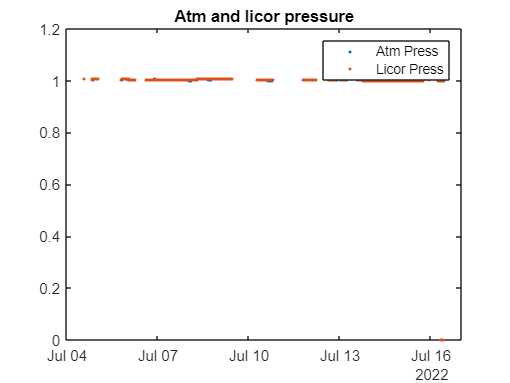


% Juntas
plot(A.Date, A.atmPress2, ".")
hold on
plot(A.Date, A.licorPress2, ".")
hold off
title("Atm and licor pressure")
legend("Atm Press", "Licor Press")

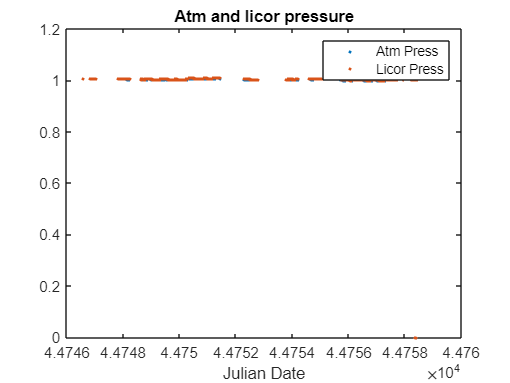

%ylim([0.97 1.03])

plot(A.JulianDate, A.atmPress2, ".")
hold on
plot(A.JulianDate, A.licorPress2, ".")
hold off
title("Atm and licor pressure")
legend("Atm Press", "Licor Press")
xlabel("Julian Date")

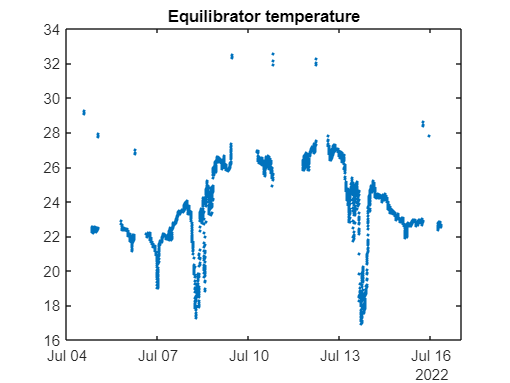

%ylim([0.97 1.03])


% Temperaturas

% Equ Temp
plot(A.Date, A.equTemp, ".")
title("Equilibrator temperature")

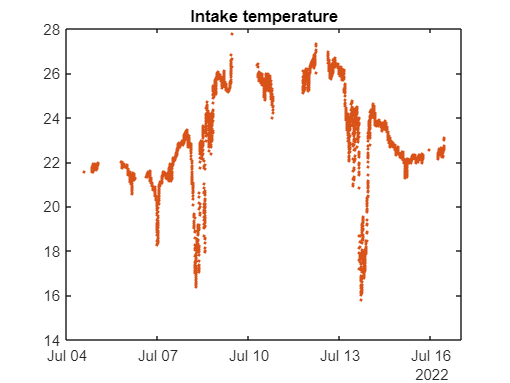

%ylim([14 32])

% Intake temp
plot(A.Date, A.IntakeTemp, ".", "Color", "#D95319")
title("Intake temperature")

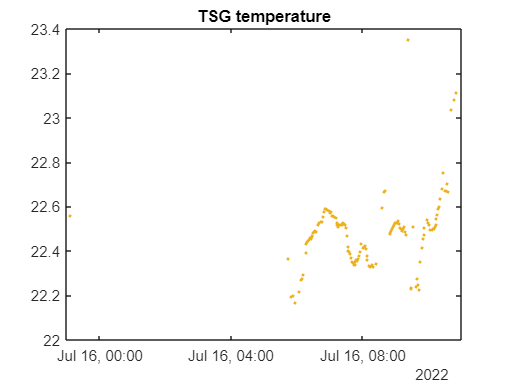

%ylim([11 24])
% A veces da valores de miles que habría que quitar

% TSG temp
plot(A.Date, A.TSGTemp, ".", "Color", 	"#EDB120")
title("TSG temperature")

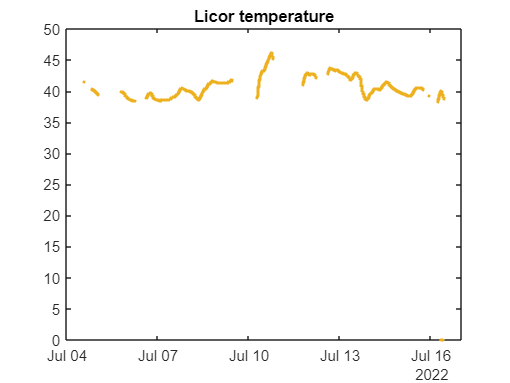

%ylim([14 30])
% A veces da valores de miles que habría que quitar 

% Licor temp
plot(A.Date, A.licorTemp, ".", "Color", "#EDB120")
title("Licor temperature")

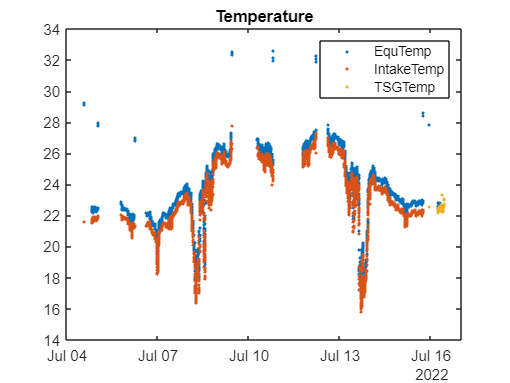

% ylim([14 30])

% Todas juntas menos licor temp
plot(A.Date, A.equTemp, ".")
hold on
plot(A.Date, A.IntakeTemp, ".")
hold on
plot(A.Date, A.TSGTemp, ".")
hold off
title("Temperature")
legend("EquTemp", "IntakeTemp", "TSGTemp")

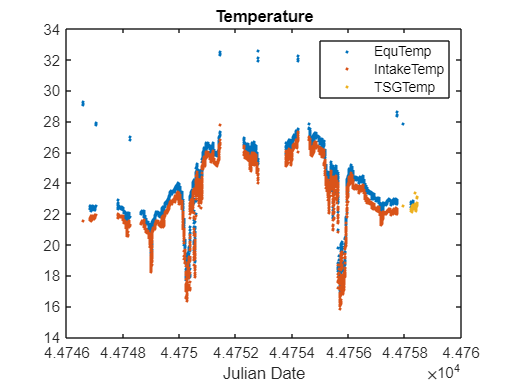

% ylim([15 24])
%ylim([12 32])

plot(A.JulianDate, A.equTemp, ".")
hold on
plot(A.JulianDate, A.IntakeTemp, ".")
hold on
plot(A.JulianDate, A.TSGTemp, ".")
hold off
title("Temperature")
legend("EquTemp", "IntakeTemp", "TSGTemp")
% ylim([15 30])
xlabel("Julian Date")

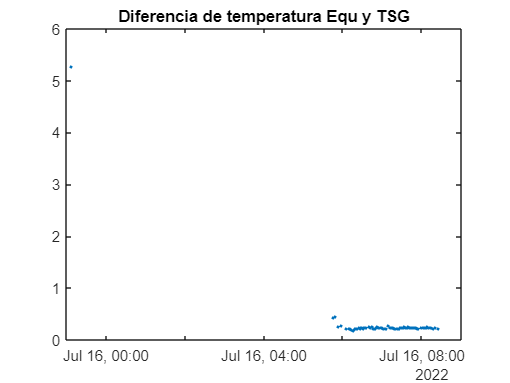

%ylim([12 32])


% Diferencias de temperatura

% Equ y TSG
plot(A.Date, A.DiffEquTSG, ".")
title("Diferencia de temperatura Equ y TSG")

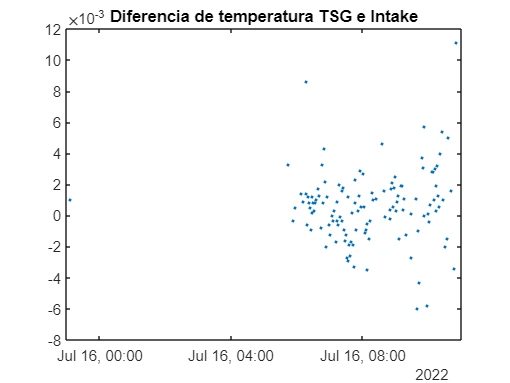

%ylim([-0.5 2.5])

% TSG e Intake
plot(A.Date, A.DiffTSGint, ".")
title("Diferencia de temperatura TSG e Intake")

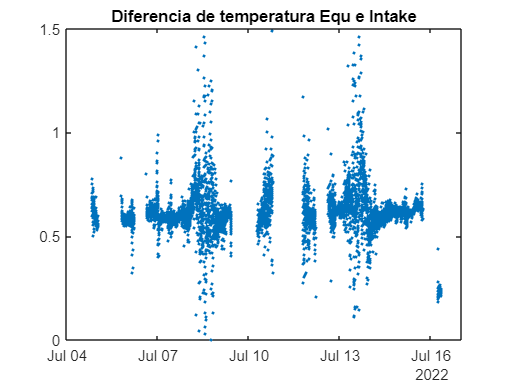

%ylim([0 2])

% Equ e Intake
plot(A.Date, A.DiffEquInt, ".")
title("Diferencia de temperatura Equ e Intake")
%ylim([0 2])
hold on
yline(1.5)
hold off

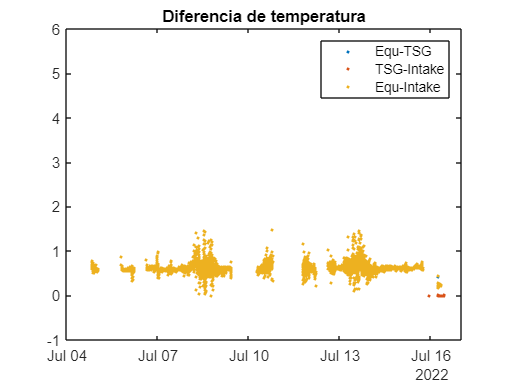


% Juntas 
plot(A.Date, A.DiffEquTSG, ".")
hold on
plot(A.Date, A.DiffTSGint, ".")
hold on
plot(A.Date, A.DiffEquInt, ".")
hold off
title("Diferencia de temperatura")
legend("Equ-TSG", "TSG-Intake", "Equ-Intake")

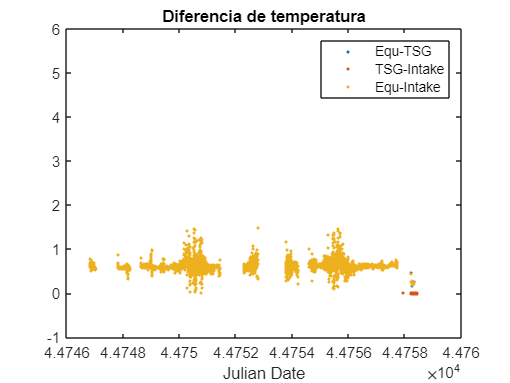

%ylim([-0.5 2])

plot(A.JulianDate, A.DiffEquTSG, ".")
hold on
plot(A.JulianDate, A.DiffTSGint, ".")
hold on
plot(A.JulianDate, A.DiffEquInt, ".")
hold off
title("Diferencia de temperatura")
legend("Equ-TSG", "TSG-Intake", "Equ-Intake")
xlabel("Julian Date")

%ylim([-0.5 2])

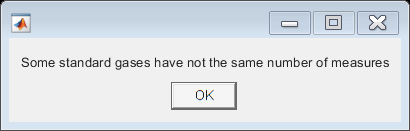

STD1Rows = find(A.Type == "STD1");
STD2Rows = find(A.Type == "STD2");
STD3Rows = find(A.Type == "STD3");
STD4Rows = find(A.Type == "STD4");
STD4sRows = find(A.Type == "STD4s");
STD1zRows = find(A.Type == "STD1z");
EQUrows = find(A.Type == "EQU");
STDsRows = find(A.Type == "STD1"| A.Type == "STD2" | A.Type == "STD3" | A.Type == "STD4" | A.Type == "STD4s" | A.Type == "STD1z");

% Indicar si los estándares presentan el mismo número de medidas (filas)
if any([size(STD1Rows) ~= size(STD2Rows), size(STD1Rows) ~= size(STD3Rows), size(STD1Rows) ~= size(STD4Rows), size(STD2Rows) ~= size(STD3Rows), size(STD2Rows) ~= size(STD4Rows), size(STD3Rows) ~= size(STD4Rows)])
   msgbox("Some standard gases have not the same number of measures");
else 
   msgbox("Same number of measures for all standard gases");
end

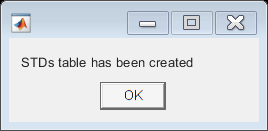

% Crear tabla si todos los gases tienen el mismo número de medidas
if numel(STD1Rows) == numel(STD2Rows) && numel(STD2Rows) == numel(STD3Rows) && numel(STD3Rows) == numel(STD4Rows)
    STDs = [STD1Rows, STD2Rows, STD3Rows, STD4Rows]; % Crear tabla con los índices de los estándares
    msgbox("STDs table has been created");
else
    msgbox("One or more gases have different number of grouped measures");
end

STD1column = A.CO2Umm;
STD2column = A.CO2Umm;
STD3column = A.CO2Umm;
STD4column = A.CO2Umm;

nonSTD1 = find(A.Type ~= "STD1");
nonSTD2 = find(A.Type ~= "STD2");
nonSTD3 = find(A.Type ~= "STD3");
nonSTD4 = find(A.Type ~= "STD4");

% Hacer NaN en los valores que no corresponden a cada estándar
STD1column(nonSTD1) = NaN;
STD2column(nonSTD2) = NaN;
STD3column(nonSTD3) = NaN;
STD4column(nonSTD4) = NaN;

% Combinar las columnas de cada estándar con la Julian Date
julianDate = A{:, "JulianDate"};
STDtable = table(STD1column, STD2column, STD3column, STD4column, julianDate);

interpol = fillmissing(STDtable(:, 1:4), 'linear', 'SamplePoints', STDtable.julianDate);

A = [A, interpol];

% Calcular valor de la pendiente y de la intersección
standardVals = [0, 249.37, 398.49, 542.24];
STDcolumns = [A.STD1column, A.STD2column, A.STD3column, A.STD4column];
line = zeros(numel(A.STD2column), 2);

for i=1:numel(STDcolumns(:, 1))
    line(i, :) = polyfit(standardVals(:), STDcolumns(i, :), 1);
end

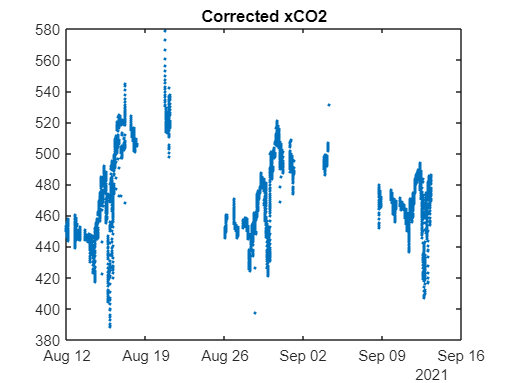

% Corregir valores de CO2

CO2corr = zeros(numel(line(:, 1)), 1);

for i=1:numel(line(:, 1))
    CO2corr(i) = polyval(line(i, :), A.CO2Umm(i));
end

A.CO2corr = CO2corr;
A = movevars(A, "CO2corr", "After", "CO2Umm");

% Representar valores corregidos
plot(A.Date(A.Type == "EQU"), A.CO2corr(A.Type == "EQU"), ".")
title("Corrected xCO2")

Af = A(A.latitude < 29.20 & A.latitude > 28.50 & A.longitude < -15.3 & A.longitude > -15.6 & A.Type == "EQU", :);

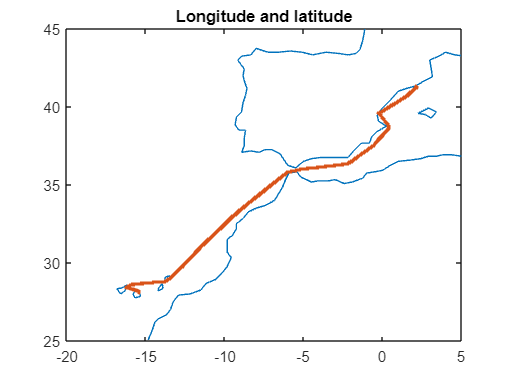

plot(coastlon, coastlat)
hold on 
plot(A.longitude, A.latitude, ".")
hold off
title("Longitude and latitude")
xlim([-20 5])
ylim([25 45])

Af = A(A.latitude < 29.20 & A.latitude > 28.50 & A.Type == "EQU", :);

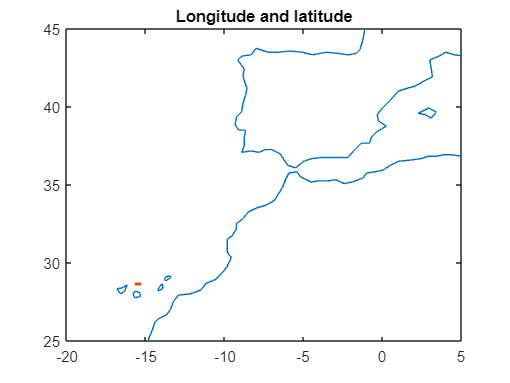

plot(coastlon, coastlat)
hold on 
plot(Af.longitude, Af.latitude, ".")
hold off
title("Longitude and latitude")
xlim([-20 5])
ylim([25 45])

data = Af(:, ["Date","JulianDate","latitude","longitude", "IntakeTemp", "SAL"]);
writetable(data, 'nearSTOC.csv', 'Delimiter', '\t')

writetable(A, '2021.csv', 'Delimiter', '\t')

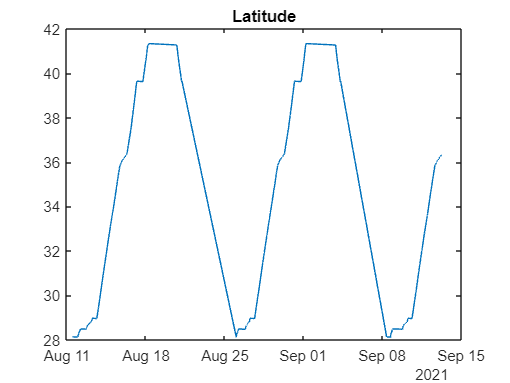

A.GPSDate.Format = "dd/MM/uuuu HH:mm:ss";
A.gpsTime.Format = "dd/MM/uuuu HH:mm:ss";

A.Date = A.GPSDate + timeofday(A.gpsTime);
A.JulianDate = exceltime(A.Date);

% Coordenadas
plot(A.Date, A.latitude)
title("Latitude")

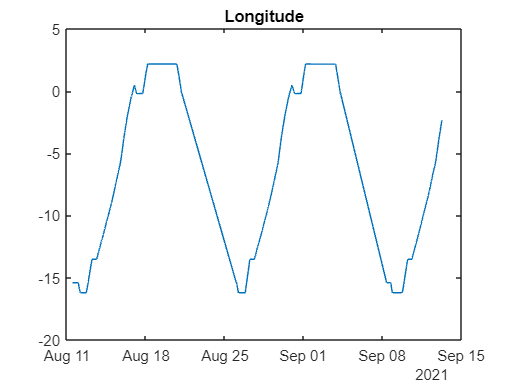


plot(A.Date, A.longitude)
title("Longitude")


% Obtener las coordenadas máximas y mínimas medidas para comprobar si hay algún error
coord = table(min(A.longitude), min(A.latitude), max(A.longitude), max(A.latitude), 'VariableNames', {'minLon', 'minLat', 'maxLon', 'maxLat'});

load coastlines
plot(coastlon, coastlat)
hold on 
plot(A.longitude, A.latitude, ".")
hold off
title("Longitude and latitude")
xlim([-20 5])
ylim([25 45])

Af = A(A.latitude < 29.20 & A.latitude > 28.50 & A.longitude < -15.4 & A.longitude > -15.6 & A.Type == "EQU", :);

plot(coastlon, coastlat)
hold on 
plot(Af.longitude, Af.latitude, ".")
hold off
title("Longitude and latitude")
xlim([-20 5])
ylim([25 45])

data = Af(:, ["Date","JulianDate","latitude","longitude","CO2Umm", "pCO2sw","fCO2sw", "IntakeTemp", "SAL"]);

writetable(data, 'nearESTOC2021.csv', 'Delimiter', '\t')